**ΤΕΧΝΟΛΟΓΙΑ ΉΧΟΥ **

**Εργασία 2 **

**Παναγιώτα Μωραΐτη** 

α) Εξαγωγή Συντελεστών LPC

Για την επεξεργασία και μοντελοποίηση της ανθρώπινης ομιλίας με γραμμική πρόβλεψη, χωρίζουμε την φωνητική κοιλότητα (στοματοφάρυγγα) σε p μικρούς κυλίνδρους. Για την συνάρτηση μεταφοράς χρειάζεται να υπολογίσουμε τα G (κέρδος) και α (συντελεστές του φίλτρου πόλων) δηλαδή τους συντελεστές γραμμικής πρόβλεψης που σχετίζονται με τα γεωμετρικά χαρακτηριστικά των κυλίδρων.

Με τη παραπάνω διαδικασία, το πρόβλημα της μοντελοποίησης διαιρείται στο πρόβλημα της  μοντελοποίησης των διακριτών αυτών κυλίνδρων. 

[x, fs] = audioread('voice.wav');
frame = 256;
ovrlp = 0.25;
soundsc(x, fs); % Initial sound
X = frame_wind (x, frame, ovrlp);
X = X(:,1:785); 

[a,G] = lpcs_total(X,20);

Επειδή στον πίνακα X στις τρεις τελευταίες στήλες υπάρχουν NaN τις έχουμε κόψει για να μην μας δημιουργούν πρόβλημα στους παρακάτω υπολογισμούς (a, G, SNR).

β) Εξαγωγή Σφάλματος Γραμμικής Πρόβλεψης

e = calculate_error(X,a);

Το σφάλμα της γραμμικής πρόβλεψης είναι μια πολύ καλή εκτίμηση του σήματος που παράγεται από τις φωνητικές χορδές.

Ο υπολογισμός του σφάλματος μπορεί να απλοποιηθεί και αντί να υπολογιστεί από τη σχέση που δίνεται στην εκφώνηση εμείς το υπολογίσαμε με την εντολή filter(Αριθμητής της H(z), Παρονομαστής της H(z) = 1, σήμα εισόδου = frame του x), όπου H(z) η συνάρτηση μεταφοράς.

γ) Τέλεια ανακατασκευή

X = frame_wind (x, frame, ovrlp);
X = X(:,1:785);

[a,G] = lpcs_total(X,20);
Y = filter_func(X,G,a,e);

y = frame_recon (Y, ovrlp);
soundsc(y, fs); % Final sound

Μετά το φιλτράρισμα του σφάλματος παρατηρούμε ότι οι έμφωνοι φθόγγοι αναπαράγονται κανονικά, ενώ οι άφωνοι αναπαράγουν περισσότερο θόρυβο. Οπότε, η ανακατασκευή έχει κάποιες αλλοιώσεις.

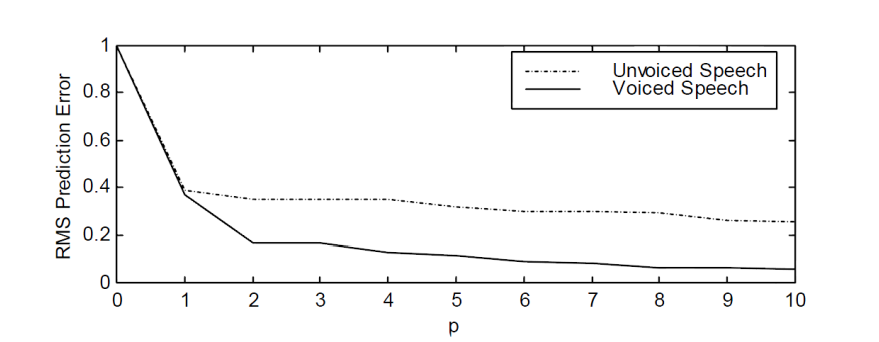

Σχέση μέσου όρου τετραγωνικού σφάλματος της γραμμικής πρόβλεψης σε συνάρτηση με την τάξη της γραμμικής πρόβλεψης  

(Πλήθος Συντελεστών p)

Παρατηρούμε ότι όσο πιο μεγάλο p έχουμε, τόσο μικρότερο είναι το σφάλμα σφάλμα e[n].

x = transpose(x);
x = x(1,1:size(y,2));

SNR = 10*log10(sum(x.^2)/sum((x-y).^2));
r = snr(x,x-y); % x-y is the noise, y is the filtered signal

Με το SNR (signal to noise ratio) υπολογίζουμε το ποσοστό του θορύβου που εισάγεται στο σήμα μας. Ο υπολογισμός έγινε με δύο τρόπους, με τον λογαριθμικό τύπο και με την συνάρτηση του matlab και βρήκαμε το ίδιο αποτέλεσμα.

δ) Voice Morphing μεταξύ ίδιου φύλου 

Για τους άνδρες Voice Morphing

frame = 256;
ovrlp = 0.25;
[x1, fs] = audioread('umale_1.wav');
soundsc(x1, fs); % Initial sound1

[x2, fs] = audioread('umale_2.wav');
soundsc(x2, fs); % Initial sound2

X1 = frame_wind (x1, frame, ovrlp);
X2 = frame_wind (x2, frame, ovrlp);
[y1, y2] = voice_morphing(X1,X2);

soundsc(y1, fs); % Final sound1

soundsc(y2, fs); % Final sound2

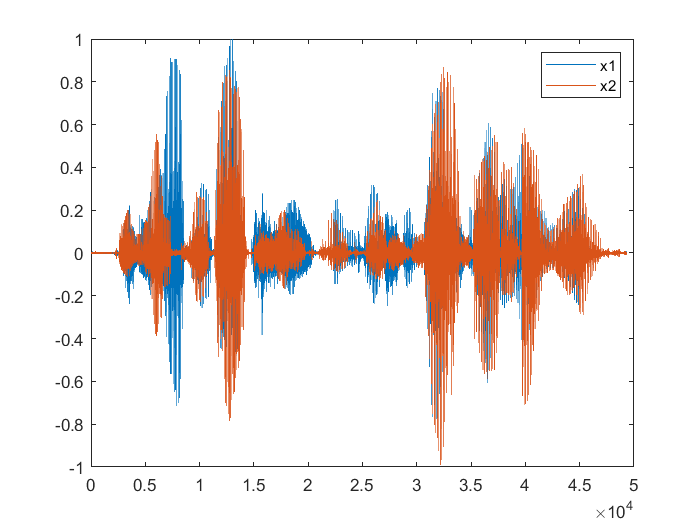

plot(x1);
hold on;
plot(x2);
hold off;
legend('x1', 'x2')

Παραπάνω, κατά το φιλτράρισμα στην φωνή του πρώτου ομιλητή χρησιμοποιούμε το κέρδος και τους συντελεστές γραμμικής πρόβλεψης του δεύτερου ομιλητή και αντιστρόφως. Με αυτόν τον τρόπο οι δύο ομιλητές αλλάζουν φωνές. Αυτό συμβαίνει επειδή τα a, G φέρουν τα χαρακτηριστικά της περιβάλλουσας, δηλαδή τα χαρακτηριστικά της ταυτότητας του κάθε ομιλητή.

Οι φασματικές περιβάλουσες (spectral envelopes), περιέχουν το κύριο μέρος της ηχητικής πληροφορίας.

Βέβαια, το αποτέλεσμα ακουστικά δεν είναι τέλειο. Οι αλλοιώσεις που παρατηρούνται οφείλονται στο γεγονός ότι οι θεμελιώδεις συχνότητες (pitch) των ομιλητών δεν είναι ίδιες.

Για τις γυναίκες Voice Morphing

frame = 256;
ovrlp = 0.25;
[x1, fs] = audioread('ufemale_1.wav');
soundsc(x1, fs); % Initial sound1

[x2, fs] = audioread('ufemale_2.wav');
soundsc(x2, fs); % Initial sound2

X1 = frame_wind (x1, frame, ovrlp);
X2 = frame_wind (x2, frame, ovrlp);
[y1, y2] = voice_morphing(X1,X2);

soundsc(y1, fs); % Final sound1

soundsc(y2, fs); % Final sound2

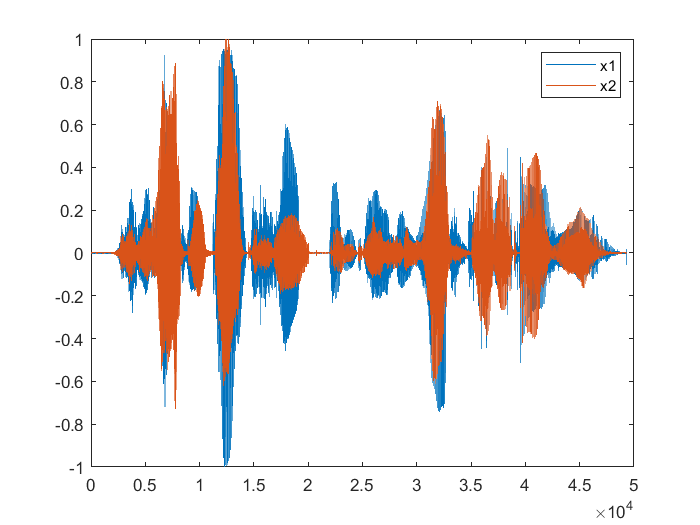

plot(x1);
hold on;
plot(x2);
hold off;
legend('x1', 'x2')

Η τεχνική που αναφέραμε παραπάνω, λειτουργεί εξίσου ικανοποιητικά και για τις γυναικείες φωνές.

Από τα δύο διαγράμματα παρατηρούμε ότι το voice morphing είναι πιο επιτυχημένο στις γυναίκες. Αυτό μπορεί να οφείλεται στο γεγονός ότι στο 2ο διάγραμμα οι αρχικές φωνές των γυναικών συμπίπτουν σχεδόν μεταξύ τους και μόνο κάποιες κορυφές ξεφεύγουν. Ενώ στο 1ο διάγραμμα ειδικά στην αρχή, η μία κυματομορφή ξεφεύγει κατά πολύ από την άλλη (ενώ η πορτοκαλί μηδενίζεται, η μπλε μεγιστοποιείται).

ε) Voice Morphing σε διαφορετικά φύλα

frame = 256;
ovrlp = 0.25;
[x1, fs] = audioread('umale_1.wav');
soundsc(x1, fs); % Initial sound1

[x2, fs] = audioread('ufemale_1.wav');
soundsc(x2, fs); % Initial sound2

X1 = frame_wind (x1, frame, ovrlp);
X2 = frame_wind (x2, frame, ovrlp);
[y1, y2] = voice_morphing(X1,X2);

soundsc(y1, fs); % Final sound1

soundsc(y2, fs); % Final sound2

 Voice Morphing σε διαφορετικά φύλα για τις άλλες 2 φωνές

frame = 256;
ovrlp = 0.25;
[x1, fs] = audioread('umale_2.wav');
soundsc(x1, fs); % Initial sound1

[x2, fs] = audioread('ufemale_2.wav');
soundsc(x2, fs); % Initial sound2

X1 = frame_wind (x1, frame, ovrlp);
X2 = frame_wind (x2, frame, ovrlp);
[y1, y2] = voice_morphing(X1,X2);

soundsc(y1, fs); % Final sound1

soundsc(y2, fs); % Final sound2

Η αλλαγή των δύο φωνών σε διαφορετικά φύλα δεν είναι ικανοποιητική και οι αλλοιώσεις είναι τεράστιες.

Αυτό οφείλεται στο γεγονός ότι η διαφορά στις θεμελιώδεις συχνότητες ανδρών και γυναικών είναι πολύ μεγάλες.

Male pitch: 125Hz

Female pitch: 200Hz

στ) Αναγνώριση ταυτότητας ομιλητή 

Για τους άνδρες

frame = 256;
ovrlp = 0.5;
[x1, fs] = audioread('umale_1.wav');
[x2, fs] = audioread('umale_2.wav');

X1 = frame_wind (x1, frame, ovrlp);
X2 = frame_wind (x2, frame, ovrlp);

[a1,G1] = lpcs_total(X1,30);
[a2,G2] = lpcs_total(X2,30);

%Speaker1 is the 1st parameter of the function
%Number 1 shows we use for recognition the matrix a from the 1st parameter of the function
voice_recognition(a1, a2, 1);

The voice 1 belongs to the speaker 1


%Speaker2 is the 2nd parameter of the function
%Number 2 shows we use for recognition the matrix a from the 2nd parameter of the function
voice_recognition(a1, a2, 2);

The voice 2 belongs to the speaker 2


Αναγνώριση ταυτότητας ομιλητή για τις γυναίκες

frame = 256;
ovrlp = 0.5;
[x1, fs] = audioread('ufemale_1.wav');
[x2, fs] = audioread('ufemale_2.wav');

X1 = frame_wind (x1, frame, ovrlp);
X2 = frame_wind (x2, frame, ovrlp);

[a1,G1] = lpcs_total(X1,30);
[a2,G2] = lpcs_total(X2,30);

voice_recognition(a1, a2, 1);

The voice 1 belongs to the speaker 1


voice_recognition(a1, a2, 2);

The voice 2 belongs to the speaker 2


Το σύστημα λειτουργεί επιτυχώς, όταν συγκρίνουμε μεταξύ δύο ομιλητών.

Σύστημα αναγνώρισης φωνής, που θα αναγνωρίζει τον 1ο ομιλητή (umale1) από τους υπόλοιπους 3 ομιλητές.

**Πρώτος τρόπος:**

Η σύγκριση γίνεται μεταξύ τεσσάρων ομιλητών ταυτόχρονα.

frame = 256;
ovrlp = 0.5;
[x1, fs] = audioread('umale_1.wav');
[x2, fs] = audioread('umale_2.wav');
[x3, fs] = audioread('ufemale_1.wav');
[x4, fs] = audioread('ufemale_2.wav');

X1 = frame_wind (x1, frame, ovrlp);
X2 = frame_wind (x2, frame, ovrlp);
X3 = frame_wind (x3, frame, ovrlp);
X4 = frame_wind (x4, frame, ovrlp);

[a1,G1] = lpcs_total(X1,30);
[a2,G2] = lpcs_total(X2,30);
[a3,G3] = lpcs_total(X3,30);
[a4,G4] = lpcs_total(X4,30);

voice_recognition2(a1,a2,a3,a4,1);

The voice 1 belongs to the speaker 2


voice_recognition2(a1,a2,a3,a4,2);

The voice 2 belongs to the speaker 2


voice_recognition2(a1,a2,a3,a4,3);

The voice 3 belongs to the speaker 3


voice_recognition2(a1,a2,a3,a4,4);

The voice 4 belongs to the speaker 4


Ο παραπάνω τρόπος δε δουλεύει, γιατί το σφάλμα είναι μεγάλο στον υπολογισμό των αποστάσεων. 

Όταν στην σύγκριση συμμετέχουν και οι γυναίκες, παίρνουν κάποιες από τις ελάχιστες αποστάσεις του 1 λανθασμένα. Οπότε ο 1 μένει με λιγότερες ελάχιστες αποστάσεις και ο 2 μένει σχεδόν με όσες είχε αρχικά. Οπότε, πλέον ο 2 έχει περισσότερες ελάχιστες αποστάσεις, γι' αυτό στην 1η σύγκριση κερδίζει και έχουμε λάθος αποτέλεσμα (The voice 1 belongs to the speaker 2).

**Δεύτερος τρόπος:**

Παρακάτω συγκρίνουμε τους ομιλητές ανά δύο, όπου η αναγώριση των ομιλητών έγινε με επιτυχία, χρησιμοποιώντας μόνο τις ευκλέιδειες αποστάσεις για την αναγώριση των ομιλητών.

voice_recognition3(a1,a2,a3,a4,1);

The voice 1 belongs to the speaker 1


voice_recognition3(a1,a2,a3,a4,2);

The voice 2 belongs to the speaker 2


voice_recognition3(a1,a2,a3,a4,3);

The voice 3 belongs to the speaker 3


voice_recognition3(a1,a2,a3,a4,4);

The voice 4 belongs to the speaker 4


**Τρίτος τρόπος:**

Βέβαια, ο γρηγορότερος τρόπος που σκεφτήκαμε ήταν να αξιοποιήσουμε την μέση συχνότητα ταλάντωσης των φωνητικών χορδών ή αλλιώς θεμελιώδη συχνότητα Fo (pitch) των ομιλητών για να επιτευχθεί αρχικά η διάκριση μεταξύ ανδρών και γυναικών. 

Για τον άνδρα η θεμελιώδης συχνότητα βρίσκεται κοντά στον φθόγγο Β2, δηλαδή η μέση τιμή για την θεμελιώδη συχνότητα της ομιλίας σε ανδρική φωνή είναι 125 Hz, ενώ για την γυναίκα κοντά στον φθόγγο G3 , δηλαδή η μέση τιμή για την θεμελιώδη συχνότητα της ομιλίας σε γυναικεία φωνή είναι 200 Hz. Έτσι για να γίνει ορθά η διάκρισή τους θέσαμε ένα όριο, threshold στα 160 Hz.

Στη συνέχεια, συγκρίναμε τις αποστάσεις των ομιλητών ανά ζευγάρια του ίδιου φύλου. 

[m1, fs] = audioread('umale_1.wav');
[m2, fs] = audioread('umale_2.wav');
[f1, fs] = audioread('ufemale_1.wav');
[f2, fs] = audioread('ufemale_2.wav');

freq_m1 = mean(pitch(m1,fs));
freq_m2 = mean(pitch(m2,fs));
freq_f1 = mean(pitch(f1,fs));
freq_f2 = mean(pitch(f2,fs));

% voice_recognition_freqm(male1=speaker1, male2=speaker2, female1=speaker3, female2=speaker4, speakerx, frequency_of_x)

voice_recognition_freq(m1,m2,f1,f2,1,freq_m1);

The voice 1 belongs to the Speaker1 (male1)


voice_recognition_freq(m1,m2,f1,f2,2,freq_m2);

The voice 2 belongs to the Speaker2 (male2)


voice_recognition_freq(m1,m2,f1,f2,3,freq_f1);

The voice 3 belongs to the Speaker3 (female1)


voice_recognition_freq(m1,m2,f1,f2,4,freq_f2);

The voice 4 belongs to the Speaker4 (female2)
